system("make clean -f .\Makefile");

rm -f *.exe
rm -f *.exp
rm -f *.lib
rm -f *.txt


system("make main -f .\Makefile");

g++ -Wall -Wpedantic -O2 sensingArray.cpp -o sensingArray.exe



% Run Uncracked Simulation for baseline
system(".\sensingArray.exe input_no_crack.dat");
% x_no_crack = load("x.txt") * 1e6; % [μV]
Dv_no_crack = load("Dv.txt") * 1e6; % [μV]

% Run Cracked Simulation
system(".\sensingArray.exe input_crack.dat");
% x_crack = load("x.txt") * 1e6; % [μV]
Dv_crack = load("Dv.txt") * 1e6; % [μV]

% Get Crack Info
crack_info = fopen("input_crack.dat","r");
[~] = fscanf(crack_info,"is_cracked %d\n");
[pos_crack] = fscanf(crack_info,"crack_pos %f %f\n");
[len_crack] = fscanf(crack_info,"len %f\n");
[thick_crack] = fscanf(crack_info,"crack_thick %f\n");
[angled_crack] = fscanf(crack_info,"angle %f\n");

% Get ΔV Ratio, Max & Min & v Points
v_points = readmatrix("v_Points.txt");
Dv_ = Dv_crack./ Dv_no_crack;
Dv_max = max(Dv_);
Dv_min = min(Dv_);
Dv_ = (Dv_ - Dv_min)./(Dv_max - Dv_min); % Range = [0,1]

% Get Simulation Info
fp_info = fopen("info.txt","r");
N = str2double(fgetl(fp_info));
M = str2double(fgetl(fp_info));
N_sens = str2double(fgetl(fp_info));
M_sens = str2double(fgetl(fp_info));
fclose(fp_info);

% Get range of Horizontal & Vertical Scanning Points
range_horScan = 1:(N_sens - 3) * (M_sens);
range_vertScan = (N_sens - 3) * (M_sens) + 1:length(Dv_);

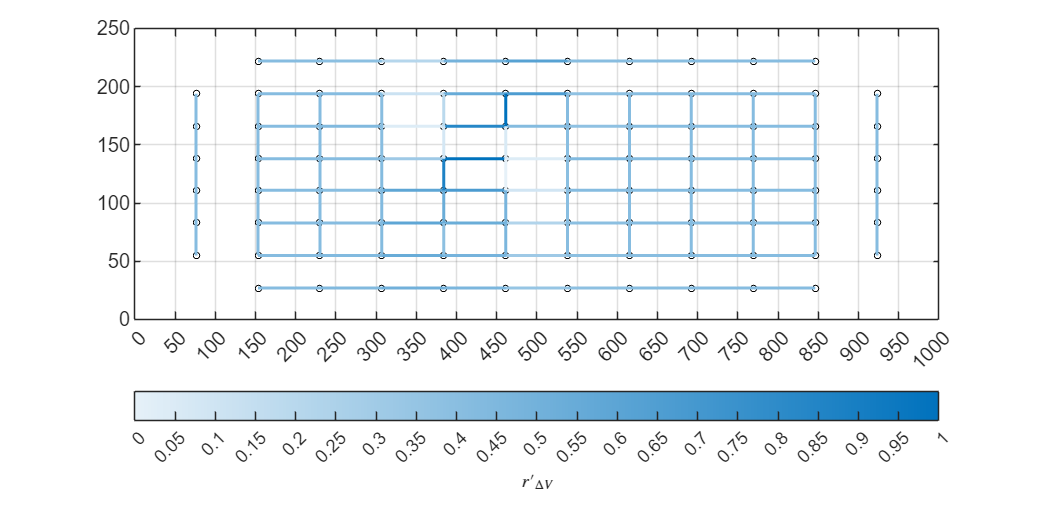

fg = figure("Position",[0,0,N,2*M]);
sz = 10;
scatter(v_points(:,1),v_points(:,3),sz,'ko')
hold on
scatter(v_points(:,2),v_points(:,4),sz,'ko')

for i = 1:length(Dv_)
    v1.x = v_points(i,1);
    v2.x = v_points(i,2);
    v1.y = v_points(i,3);
    v2.y = v_points(i,4);
    color = (sky(length(Dv_) + 1));
    color_ind = round(Dv_(i) * length(Dv_) + 1);
    plot([v1.x v2.x],[v1.y v2.y],Color=color(color_ind,:),LineWidth=1.5);
end
colormap("sky");
c = colorbar("southoutside",Ticks=0:0.05:1);
c.Label.String = "$r\prime_{\Delta V}$";
c.Label.Interpreter = 'latex';
c.Limits = [0,1];

hold off
box on
grid on
xlim([0,N])
ylim([0,M])
xticks(0 : 50 : N)
yticks(0 : 50 : M)

saveas(fg,"grid_lines","svg");

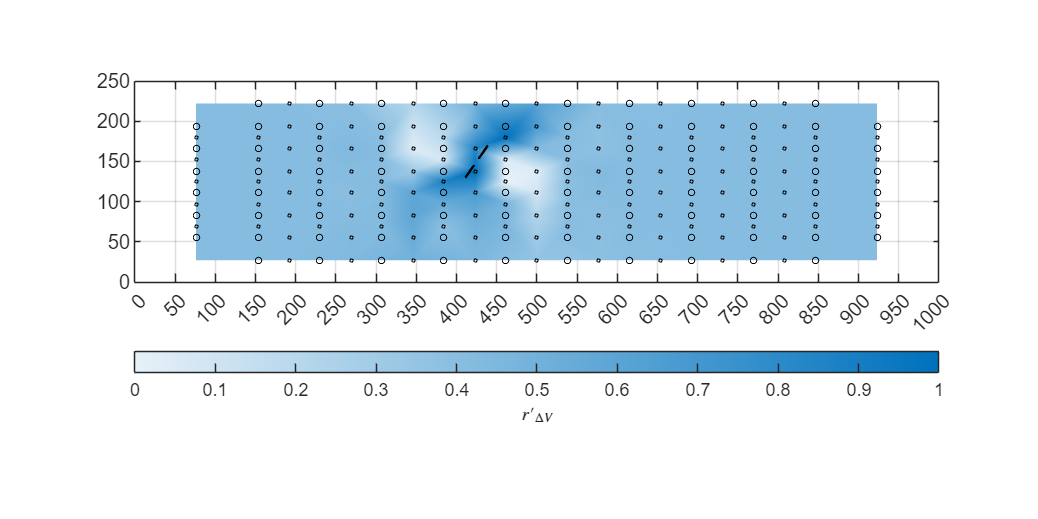

fg = figure("Position",[0,0,1000,500]);
sz = 10;

v_x = round((v_points(:,1) + v_points(:,2))/2);
v_y = round((v_points(:,3) + v_points(:,4))/2);

% Interpolation between v_points for surf plot
xgrid = linspace(min(v_x),max(v_x),N);
ygrid = linspace(min(v_y),max(v_y),M);
[xi,yi] = meshgrid(xgrid,ygrid);
V = scatteredInterpolant(v_x,v_y,Dv_);
zi = V(xi,yi);
surf(xi,yi,zi, 'EdgeAlpha', 0,'FaceColor','interp')
colormap("sky");
c = colorbar("southoutside",Ticks=0 : round(max(Dv_)/20,1) : round(max(Dv_),1));
c.Label.String = '$r\prime_{\Delta V}$';
c.Label.Interpreter = 'latex';
c.Limits = [0,round(max(Dv_),1)];

% Add Points above plot for visual
hold on
scatter3(v_points(:,1),v_points(:,3),max(Dv_),sz,'ko')
scatter3(v_points(:,2),v_points(:,4),max(Dv_),sz,'ko')
scatter3(v_x,v_y,max(Dv_),sz/4,'ko')

plot3([pos_crack(1)-len_crack/2*cosd(angled_crack) pos_crack(1)+len_crack/2*cosd(angled_crack)]/2 * 1000, ...
    [pos_crack(2)-len_crack/2*sind(angled_crack) pos_crack(2)+len_crack/2*sind(angled_crack)]/2 * 1000, ...
    [max(Dv_), max(Dv_)],'k--', 'LineWidth', 1.2)

hold off
box on
axis equal
xlim([0,N])
ylim([0,M])
xticks(0 : 50 : N)
yticks(0 : 50 : M)

view([0.000 90.000])
saveas(fg,"grid_surface","svg");

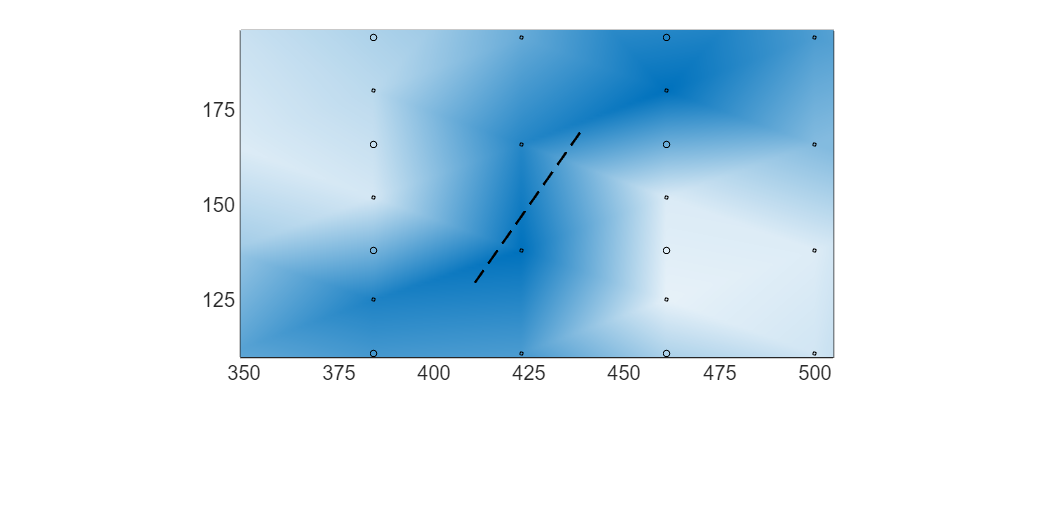

fg = figure("Position",[0,0,1000,500]);
surf(xi,yi,zi, 'EdgeAlpha', 0,'FaceColor','interp')
colormap("sky");
c = colorbar("southoutside",Ticks=0 : round(max(Dv_)/20,1) : round(max(Dv_),1));
c.Label.String = '$r\prime_{\Delta V}$';
c.Label.Interpreter = 'latex';
c.Limits = [0,round(max(Dv_),1)];
c.Visible = false;

% Add Points above plot for visual
hold on
scatter3(v_points(:,1),v_points(:,3),max(Dv_),sz,'ko')
scatter3(v_points(:,2),v_points(:,4),max(Dv_),sz,'ko')
scatter3(v_x,v_y,max(Dv_),sz/4,'ko')

x_crack_min = pos_crack(1)-len_crack/2*cosd(angled_crack);
x_crack_max = pos_crack(1)+len_crack/2*cosd(angled_crack);
y_crack_min = pos_crack(2)-len_crack/2*sind(angled_crack);
y_crack_max = pos_crack(2)+len_crack/2*sind(angled_crack);

plot3([x_crack_min, x_crack_max]/2 * 1000, ...
    [y_crack_min, y_crack_max]/2 * 1000, ...
    [max(Dv_),max(Dv_)],'k--', 'LineWidth', 1.2)

hold off
box on
axis equal
xlim(round([x_crack_min*0.85, x_crack_max*1.15]/2 * 1000,0))
ylim(round([y_crack_min*0.85, y_crack_max*1.15]/2 * 1000,0))
xticks(0 : 25 : N)
yticks(0 : 25 : M)

view([0.000 90.000])
saveas(fg,"grid_surface_zoom","svg");

% % Select Scan
% scan = 58
% x = x_crack(:,scan);
% Dv = Dv_crack(scan) % [μV]
% 
% % Extract v Point Positions
% v1.x = v_points(scan,1);
% v2.x = v_points(scan,2);
% v1.y = v_points(scan,3);
% v2.y = v_points(scan,4);
% 
% % Convert x Vector to φ Matrix
% phi = zeros(M,N);
% for i = 1:N
%     for j = 1:M
%         phi(j,i) = x(i + N * (j-1));
%     end
% end
% 
% % Plot φ Field
% figure("Position",[0,0,N,2*M]);
% X_range = 1:N;
% Y_range = 1:M;
% Dx = X_range(2) - X_range(1);
% Dy = Y_range(2) - Y_range(1);
% contour(X_range,Y_range,phi,100, ...
%     'LineStyle',"-", ...
%     "fill","off")
% 
% % Plot v Points
% hold on
% sz = 20;
% scatter(Dx*v1.x,Dy*v1.y,sz,'ko')
% scatter(Dx*v2.x,Dy*v2.y,sz,'ko')
% xlim([0,N])
% ylim([0,M])
% xticks(0 : 50 : N)
% yticks(0 : 50 : M)
% hold off
% grid on
% box on
% axis equal
% c = colorbar("southoutside");
% c.Label.String = 'Voltage $[\mu V]$';
% c.Label.Interpreter = 'latex';
% c.Limits = [round(min(x),-1), round(max(x),-1)];